clc
clear
l=[0.05 0.1 0.5 0.9]

l =     0.0500    0.1000    0.5000    0.9000



% for config 1
l1=l(1)

l1 = 0.0500

q= @(l2) (((20*100*100*10*10*l1*l1*l2*l2)/(10*10*l2*l2 + 100*100*l1*l1)).^0.5);
fplot(q,[0 1],LineWidth=2);

hold on
l1=l(2);
q= @(l2) (((20*100*100*10*10*l1*l1*l2*l2)/(10*10*l2*l2 + 100*100*l1*l1)).^0.5);
fplot(q,[0 1],LineWidth=2);

l1=l(3);
q= @(l2) (((20*100*100*10*10*l1*l1*l2*l2)/(10*10*l2*l2 + 100*100*l1*l1)).^0.5);
fplot(q,[0 1],'-.',LineWidth=2);

l1=l(4);
q= @(l2) (((20*100*100*10*10*l1*l1*l2*l2)/(10*10*l2*l2 + 100*100*l1*l1)).^0.5);
fplot(q,[0 1],'--',LineWidth=2);

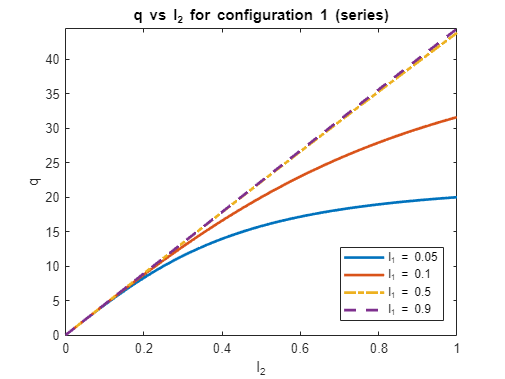

hold off

title('q vs l_2 for configuration 1 (series)')
xlabel('l_2')
ylabel('q')
legend('l_1 = 0.05','l_1 = 0.1','l_1 = 0.5','l_1 = 0.9',Location='best')

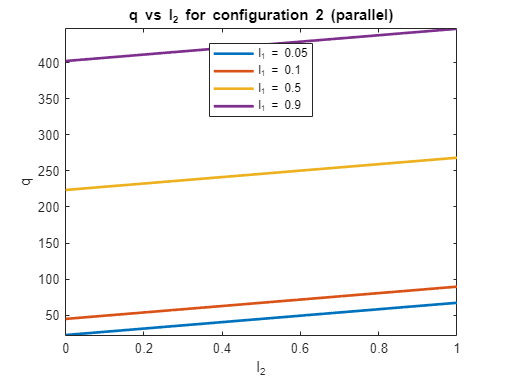


% for config 2
l1=l(1);
q=@(l2) (100*sqrt(20)*l1+10*sqrt(20)*l2);
fplot(q,[0 1],LineWidth=2);
hold on
l1=l(2);
q=@(l2) (100*sqrt(20)*l1+10*sqrt(20)*l2);
fplot(q,[0 1],LineWidth=2);
l1=l(3);
q=@(l2) (100*sqrt(20)*l1+10*sqrt(20)*l2);
fplot(q,[0 1],LineWidth=2);
l1=l(4);
q=@(l2) (100*sqrt(20)*l1+10*sqrt(20)*l2);
fplot(q,[0 1],LineWidth=2);
hold off

title('q vs l_2 for configuration 2 (parallel)')
xlabel('l_2')
ylabel('q')
legend('l_1 = 0.05','l_1 = 0.1','l_1 = 0.5','l_1 = 0.9',Location='best')